## Principal Component Analysis of Yield Curves

### **Import Data**

load YieldData.mat
dY = diff(Y{:,:});
categories = Y.Properties.VariableNames;
names = string(datestr(Y.Properties.RowTimes)); %#ok

names = names(2:end);

### Yield Curves Visualized

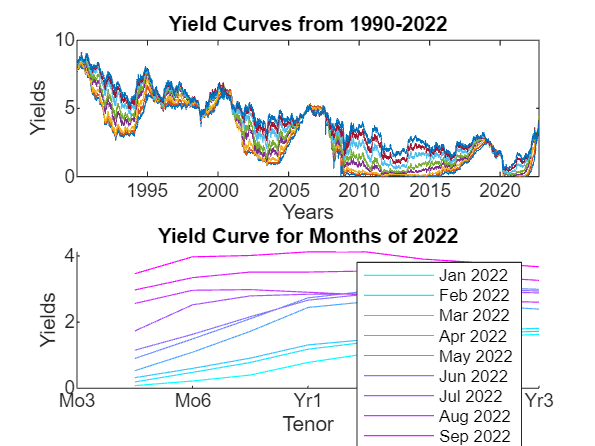

figure
subplot(2,1,1)
plot(Y.Properties.RowTimes,Y{:,:})
title('Yield Curves from 1990-2022')
xlabel('Years')
ylabel('Yields')
hAxis = subplot(2,1,2); hold on
cmap=colormap(cool(10));
plot(Y{8008,:},'Color',cmap(1,:));  % Jan 2022
plot(Y{8028,:},'Color',cmap(2,:));  % Feb 2022
plot(Y{8047,:},'Color',cmap(3,:));  % Mar 2022
plot(Y{8070,:},'Color',cmap(4,:));  % Apr 2022
plot(Y{8090,:},'Color',cmap(5,:));  % May 2022
plot(Y{8111,:},'Color',cmap(6,:));  % Jun 2022
plot(Y{8132,:},'Color',cmap(7,:));  % Jul 2022
plot(Y{8152,:},'Color',cmap(8,:));  % Aug 2022
plot(Y{8175,:},'Color',cmap(9,:));  % Sep 2022
plot(Y{8196,:},'Color',cmap(10,:));  % Oct 2022
legend('Jan 2022','Feb 2022','Mar 2022','Apr 2022','May 2022','Jun 2022','Jul 2022','Aug 2022','Sep 2022','Oct 2022')
hAxis.XTickLabel = Y.Properties.VariableNames;
title('Yield Curve for Months of 2022')
xlabel('Tenor')
ylabel('Yields')

### **Calculate Principal Componet Analysis**

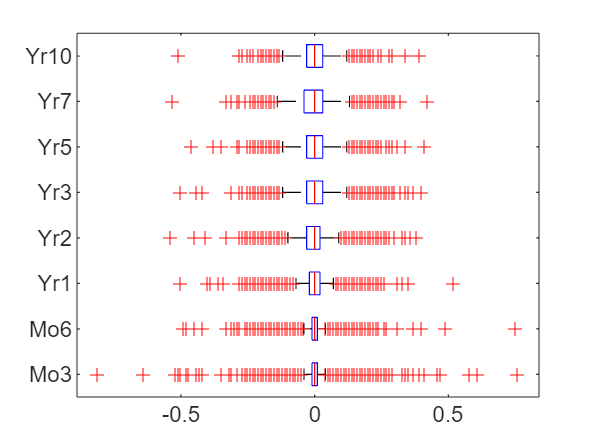

figure()
boxplot(dY,'Orientation','horizontal','Labels',categories)

## Check Pairwise Correlation

Check the pairwise correlation between the variables.

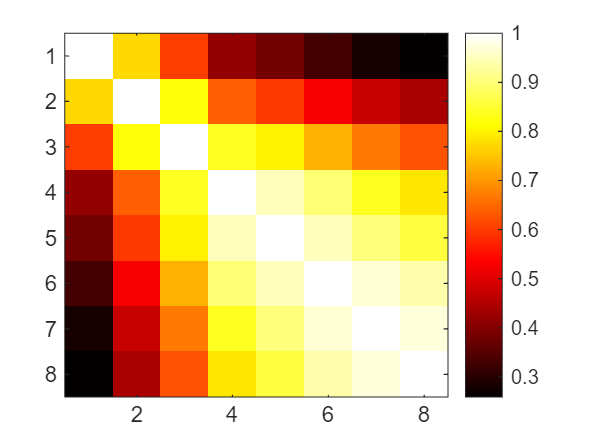

C = corr(dY,dY);
figure; imagesc(C); colormap('hot'); colorbar

## Compute Principal Components

When all variables are in the same unit, it is appropriate to compute principal components for raw data. When the variables are in different units or the difference in the variance of different columns is substantial (as in this case), scaling of the data or use of weights is often preferable.

Perform the principal component analysis by using the inverse variances of the ratings as weights.

w = 1./var(dY);
[wcoeff,score,latent,tsquared,explained] = pca(dY,'VariableWeights',w);

Or equivalently:

The following sections explain the five outputs of `pca`.

## Component Coefficients

The first output `wcoeff` contains the coefficients of the principal components.

The first three principal component coefficient vectors are:

c3 = wcoeff(:,1:3)

c3 =     0.0105    0.0305    0.0273
    0.0124    0.0210   -0.0047
    0.0158    0.0110   -0.0214
    0.0210   -0.0030   -0.0198
    0.0225   -0.0080   -0.0099
    0.0234   -0.0141    0.0064
    0.0227   -0.0175    0.0175
    0.0209   -0.0179    0.0228


These coefficients are weighted, hence the coefficient matrix is not orthonormal.

## Transform Coefficients

Transform the coefficients so that they are orthonormal.

coefforth = diag(std(dY))\wcoeff;

Note that if you use a weights vector, `w`, while conducting the `pca`, then

## Check Coefficients

The transformed coefficients are now orthonormal.

I = coefforth'*coefforth;
I(1:3,1:3)

ans =     1.0000    0.0000    0.0000
    0.0000    1.0000   -0.0000
    0.0000   -0.0000    1.0000


## Component Scores

The second output `score` contains the coordinates of the original data in the new coordinate system defined by the principal components. The `score` matrix is the same size as the input data matrix. You can also obtain the component scores using the orthonormal coefficients and the standardized ratings as follows.

cscores = zscore(dY)*coefforth;

`cscores` and `score` are identical matrices.

## Plot Component Scores

Create a plot of the first two columns of `score`.

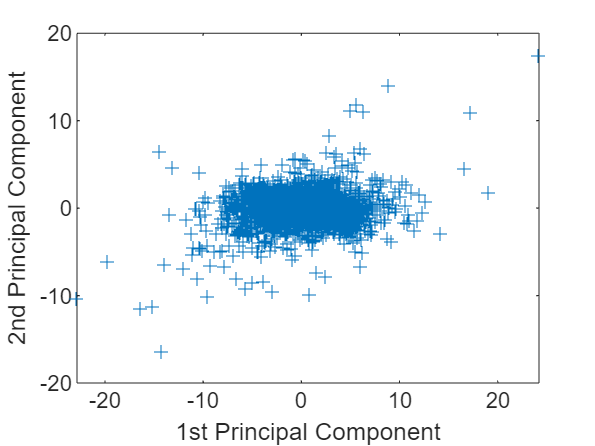

figure
plot(score(:,1),score(:,2),'+')
xlabel('1st Principal Component')
ylabel('2nd Principal Component')

## Explore Plot Interactively

Note the outlying points in the right half of the plot. You can graphically identify these points as follows.

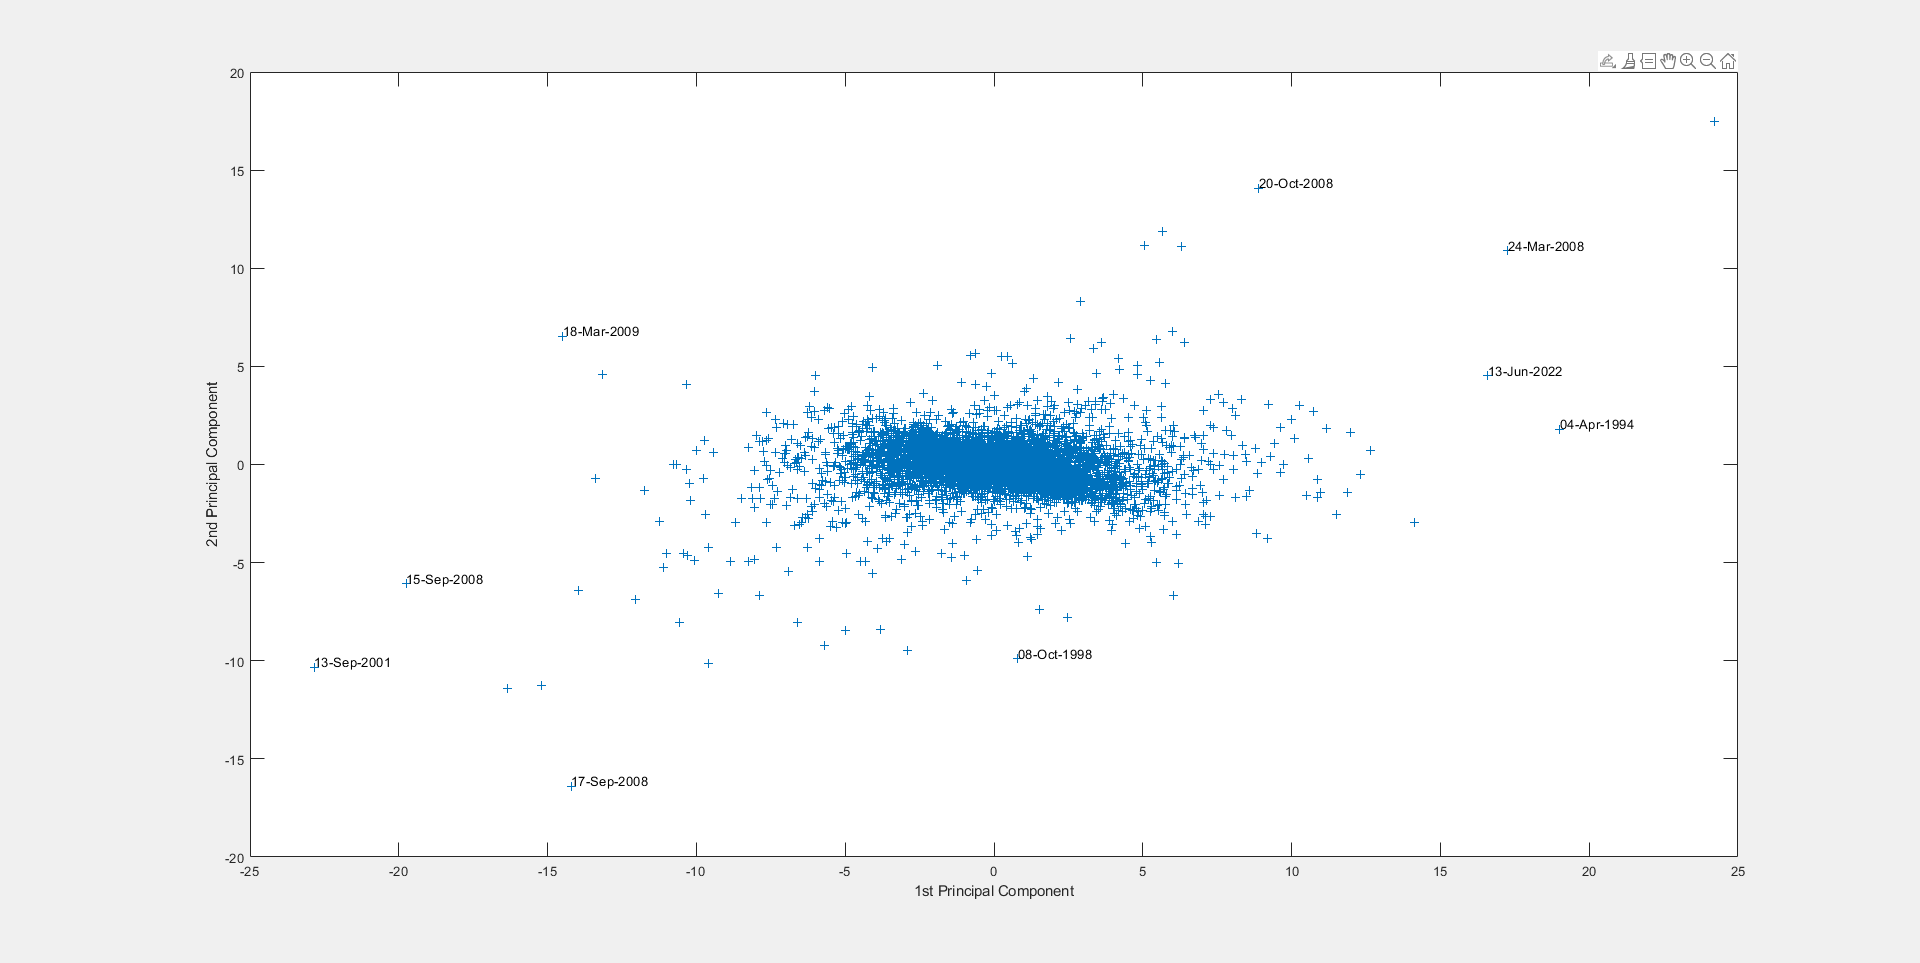

gname(names)

Move your cursor over the plot and click once near the rightmost seven points. This labels the points by their row numbers as in the following figure.

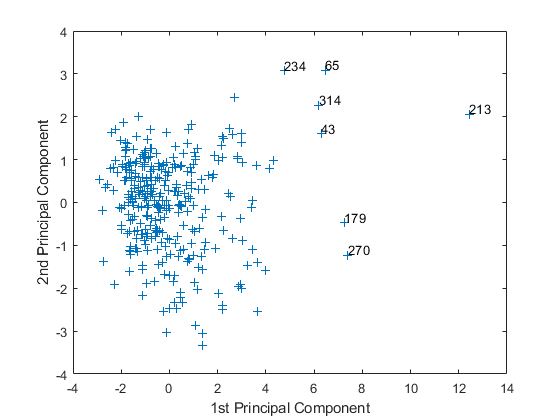

After labeling points, press **Return**.

## Create Scree Plot

Make a scree plot of the percent variability explained by each principal component.

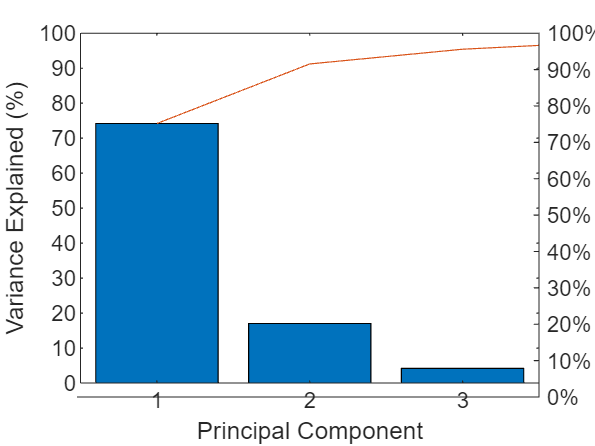

figure
pareto(explained)
xlabel('Principal Component')
ylabel('Variance Explained (%)')

## Hotelling's T-squared Statistic

The last output from `pca` is `tsquared`, which is Hotelling's $T^2$, a statistical measure of the multivariate distance of each observation from the center of the data set. This is an analytical way to find the most extreme points in the data.

[st2,index] = sort(tsquared,'descend'); % sort in descending order
extreme = index(1);
names(extreme,:)

ans = "26-Feb-2009"

## Visualize Results

Visualize both the orthonormal principal component coefficients for each variable and the principal component scores for each observation in a single plot.

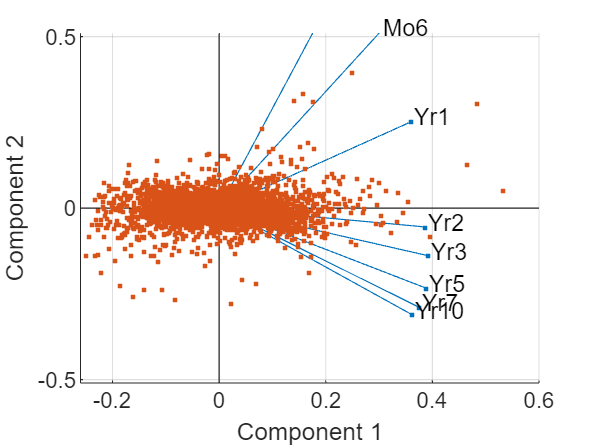

figure
biplot(coefforth(:,1:2),'Scores',score(:,1:2),'Varlabels',categories)
axis([-.26 0.6 -.51 .51]);